% 本组实验数据相当于一个对结果的仿真，一般就是例1,朝向逆时针旋转到当前方向为正，顺时针为负
% 本组数据参考update10.21中的仿真结果2,是非常准确的一组结果
% 现在本组数据是实验结果中的real_time_cir3 (lt,rt分别是这样)
% 重新跑一组
x0 = 0;          % 接收端x坐标
y0 = 0;          % 接收端y坐标
alpha = deg2rad(45);    % 接收端朝向




% 测量参数（已知）
theta1 = deg2rad(-45);   % 直接路径到达角
theta2 = deg2rad(0);     % 反射路径到达角

phi1 = deg2rad(45);      % 直接路径发射端离开角
phi2 = deg2rad(0);       % 反射路径发射端离开角

K1 = 5*sqrt(2) - 5;   % 路径差

% ==================== 十次定位求解 ====================
fprintf('开始十次模拟退火求解...\n');

开始十次模拟退火求解...


num_runs = 1;
solutions = zeros(num_runs, 5); % 存储所有解
residuals = zeros(num_runs, 1); % 存储所有残差
valid_flags = false(num_runs, 1); % 标记合法解
%定位算法*
for i = 1:num_runs
    fprintf('第 %d 次求解...\n', i);
    [solution, res] = solve_5equations_fire(x0, y0, alpha, theta1, theta2, phi1, phi2, K1);
    solutions(i, :) = solution;
    residuals(i) = res;
    
    % 检查解的合法性
    x1 = solution(1);
    y1 = solution(2);
    a = solution(4);
    b = solution(5);
    
    % 条件1: 发射端必须位于接收端朝向的同一侧
    receiver_dir = [cos(alpha), sin(alpha)];
    transmitter_vector = [x1 - x0, y1 - y0];
    dot_product = dot(receiver_dir, transmitter_vector);
    
    % 条件2: 发射端到反射面的距离至少40cm
    distance_to_wall = abs(a*x1 - y1 + b) / sqrt(a^2 + 1);
    
    if dot_product > 0 && distance_to_wall >= 0.4
        valid_flags(i) = true;
        fprintf('  第 %d 次解合法 (点积: %.4f, 距离: %.4f)\n', i, dot_product, distance_to_wall);
    else
        fprintf('  第 %d 次解不合法 (点积: %.4f, 距离: %.4f)\n', i, dot_product, distance_to_wall);
    end
    fprintf('解为: (%.4f,%.4f)\n',solution(1),solution(2));
end

第 1 次求解...


温度: 99000.000000, 当前残差: 106.894000, 最佳残差: 0.332331
温度: 98010.000000, 当前残差: 118.657407, 最佳残差: 0.332331
温度: 97029.900000, 当前残差: 143.389402, 最佳残差: 0.255728
温度: 96059.601000, 当前残差: 116.436170, 最佳残差: 0.078063
温度: 95099.004990, 当前残差: 11.193972, 最佳残差: 0.078063
温度: 94148.014940, 当前残差: 8.599421, 最佳残差: 0.078063
温度: 93206.534791, 当前残差: 94.303250, 最佳残差: 0.078063
温度: 92274.469443, 当前残差: 118.529649, 最佳残差: 0.078063
温度: 91351.724748, 当前残差: 132.437777, 最佳残差: 0.078063
温度: 90438.207501, 当前残差: 70.699892, 最佳残差: 0.078063
温度: 89533.825426, 当前残差: 106.699098, 最佳残差: 0.078063
温度: 88638.487172, 当前残差: 367.927514, 最佳残差: 0.078063
温度: 87752.102300, 当前残差: 312.280688, 最佳残差: 0.078063
温度: 86874.581277, 当前残差: 960.134839, 最佳残差: 0.078063
温度: 86005.835464, 当前残差: 184.739005, 最佳残差: 0.078063
温度: 85145.777109, 当前残差: 197.200230, 最佳残差: 0.078063
温度: 84294.319338, 当前残差: 167.660591, 最佳残差: 0.078063
温度: 83451.376145, 当前残差: 128.354384, 最佳残差: 0.078063
温度: 82616.862384, 当前残差: 36.799186, 最佳残差: 0.078063
温度: 81790.693760, 当前残差: 172.319954, 最

  第 1 次解合法 (点积: 3.7024, 距离: 2.5773)


解为: (5.2374,-0.0014)



% 选择最佳合法解
if any(valid_flags)
    valid_indices = find(valid_flags);
    [min_res, min_idx] = min(residuals(valid_indices));
    best_idx = valid_indices(min_idx);
    best_solution = solutions(best_idx, :);
    best_res = min_res;
    fprintf('\n找到 %d 个合法解，选择残差最小的解 (第 %d 次)\n', sum(valid_flags), best_idx);
else
    [best_res, best_idx] = min(residuals);
    best_solution = solutions(best_idx, :);
    fprintf('\n警告: 没有找到合法解，选择残差最小的解 (第 %d 次)\n', best_idx);
end


找到 1 个合法解，选择残差最小的解 (第 1 次)



% ==================== 结果显示 ====================
fprintf('\n=== 最终求解结果 ===\n');


=== 最终求解结果 ===


fprintf('发射端位置: (%.4f, %.4f)\n', best_solution(1), best_solution(2));

发射端位置: (5.2374, -0.0014)


fprintf('发射端朝向: %.4f rad (%.2f°)\n', best_solution(3), best_solution(3)*180/pi);

发射端朝向: 2.3748 rad (136.07°)


fprintf('反射面参数: a=%.4f, b=%.4f\n', best_solution(4), best_solution(5));

反射面参数: a=0.0097, b=2.5251


fprintf('残差: %.6f\n', best_res);

残差: 0.000532



% ==================== 反射点估计 ====================
fprintf('\n=== 反射点估计 ===\n');


=== 反射点估计 ===



% 从解中提取参数
x1 = best_solution(1);  % 发射端x坐标
y1 = best_solution(2);  % 发射端y坐标
beta = best_solution(3); % 发射端朝向
a = best_solution(4);   % 反射面参数a (斜率)
b = best_solution(5);   % 反射面参数b (截距)

% 反射面方程: y = a*x + b
fprintf('反射面方程: y = %.4f*x + %.4f\n', a, b);

反射面方程: y = 0.0097*x + 2.5251



% 计算反射点位置
dir_T2Q = [cos(beta + phi2), sin(beta + phi2)];
dir_R2Q = [cos(alpha + theta2), sin(alpha + theta2)];

% 求解反射点Q的坐标
t = (a*x1 + b - y1) / (sin(beta+phi2) - a*cos(beta+phi2));
Qx = x1 + t * cos(beta+phi2);
Qy = y1 + t * sin(beta+phi2);

fprintf('反射点Q坐标: (%.4f, %.4f)\n', Qx, Qy);

反射点Q坐标: (2.5887, 2.5502)



% 验证反射点是否在反射面上
reflection_check = Qy - (a*Qx + b);
fprintf('反射面验证: Qy - (a*Qx + b) = %.6f\n', reflection_check);

反射面验证: Qy - (a*Qx + b) = 0.000000



% 计算距离验证
dist_TQ = sqrt((Qx - x1)^2 + (Qy - y1)^2);
dist_QR = sqrt((Qx - x0)^2 + (Qy - y0)^2);
dist_TR_direct = sqrt((x1 - x0)^2 + (y1 - y0)^2);

fprintf('\n距离验证:\n');


距离验证:


fprintf('发射端到反射点距离: %.4f\n', dist_TQ);

发射端到反射点距离: 3.6778


fprintf('反射点到接收端距离: %.4f\n', dist_QR);

反射点到接收端距离: 3.6339


fprintf('反射路径总长度: %.4f\n', dist_TQ + dist_QR);

反射路径总长度: 7.3117


fprintf('直接路径长度: %.4f\n', dist_TR_direct);

直接路径长度: 5.2374


fprintf('路径差: %.4f (理论值: %.4f)\n', dist_TQ + dist_QR - dist_TR_direct, K1);

路径差: 2.0743 (理论值: 2.0711)


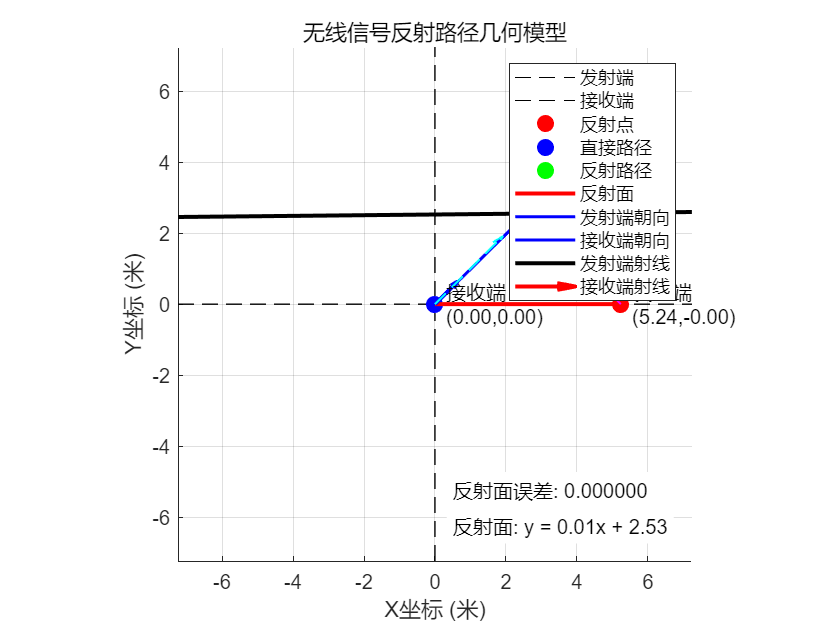


% ==================== 可视化 ====================
figure;
hold on;
grid on;
axis equal;

% 设置坐标轴范围
axis_range = max(5, max(abs([x1, y1, Qx, Qy])) + 2);
xlim([-axis_range, axis_range]);
ylim([-axis_range, axis_range]);

% 绘制坐标轴
plot([-axis_range, axis_range], [0, 0], 'k--', 'LineWidth', 0.5);
plot([0, 0], [-axis_range, axis_range], 'k--', 'LineWidth', 0.5);

% 绘制发射端和接收端
plot(x1, y1, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
plot(x0, y0, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');

% 绘制反射点
plot(Qx, Qy, 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

% 绘制直接路径
plot([x1, x0], [y1, y0], 'r-', 'LineWidth', 2);

% 绘制反射路径
plot([x1, Qx], [y1, Qy], 'b-', 'LineWidth', 1.5);
plot([Qx, x0], [Qy, y0], 'b-', 'LineWidth', 1.5);

% 绘制反射面 (y = a*x + b)
x_range = [-axis_range, axis_range];
y_range = a * x_range + b;
plot(x_range, y_range, 'k-', 'LineWidth', 2);

% 绘制方向箭头
arrow_scale = 1;
quiver(x1, y1, arrow_scale*cos(beta), arrow_scale*sin(beta), 'r', 'LineWidth', 2, 'MaxHeadSize', 1);
quiver(x0, y0, arrow_scale*cos(alpha), arrow_scale*sin(alpha), 'b', 'LineWidth', 2, 'MaxHeadSize', 1);

% 绘制射线方向
ray_scale = 3;
quiver(x1, y1, ray_scale*cos(beta+phi2), ray_scale*sin(beta+phi2), 'm--', 'LineWidth', 1, 'MaxHeadSize', 0.5);
quiver(x0, y0, ray_scale*cos(alpha+theta2), ray_scale*sin(alpha+theta2), 'c--', 'LineWidth', 1, 'MaxHeadSize', 0.5);

% 添加图例和标签
legend('发射端', '接收端', '反射点', '直接路径', '反射路径', '反射面', '发射端朝向', '接收端朝向', '发射端射线', '接收端射线');
xlabel('X坐标 (米)');
ylabel('Y坐标 (米)');
title('无线信号反射路径几何模型');

% 添加文本标注
text(x1, y1, sprintf('  发射端\n  (%.2f,%.2f)', x1, y1));
text(x0, y0, sprintf('  接收端\n  (%.2f,%.2f)', x0, y0));
text(Qx, Qy, sprintf('  反射点\n  (%.2f,%.2f)', Qx, Qy));

% 显示反射面方程
text(0.5, -axis_range+1, sprintf('反射面: y = %.2fx + %.2f', a, b), 'BackgroundColor', 'white');

% 显示验证结果
text(0.5, -axis_range+2, sprintf('反射面误差: %.6f', reflection_check), 'BackgroundColor', 'white');

hold off;






fprintf('\n可视化完成！\n');


可视化完成！
